# Basic definition of variables

a1 = 1/3

a1 = 0.3333

a1Sym = sym(1/3) 

$$a1Sym = \frac{1}{3}$$

whos a1 a1Sym

  Name       Size            Bytes  Class     Attributes

  a1         1x1                 8  double              
  a1Sym      1x1                 8  sym                 



a2sym = sym("1234567 + 1i")

$$a2sym = 1234567+\mathrm{i}$$

## Variable precision arithmetic

double_val = log(2)

double_val = 0.6931

vpaOnDouble = vpa(log(2))

$$vpaOnDouble = 0.69314718055994528622676398299518$$

vpaOnSym_17 = vpa(log(sym(2)),17)

$$vpaOnSym\_17 = 0.69314718055994531$$

vpaOnSym_20 = vpa(log(sym(2)),20)

$$vpaOnSym\_20 = 0.69314718055994530942$$

## Creating variables using symbols

syms x
A = sym("a",[1 5])

$$A = \left(\begin{array}{ccccc} a_{1} & a_{2} & a_{3} & a_{4} & a_{5} \end{array}\right)$$

syms b [1 5]

## Creating expressions

syms a
f1 = a*x^2 + b*x 

$$f1 = \left(\begin{array}{ccccc} a\,x^{2}+b_{1}\,x & a\,x^{2}+b_{2}\,x & a\,x^{2}+b_{3}\,x & a\,x^{2}+b_{4}\,x & a\,x^{2}+b_{5}\,x \end{array}\right)$$

f2 = A*x^2 + b*x

$$f2 = \left(\begin{array}{ccccc} a_{1}\,x^{2}+b_{1}\,x & a_{2}\,x^{2}+b_{2}\,x & a_{3}\,x^{2}+b_{3}\,x & a_{4}\,x^{2}+b_{4}\,x & a_{5}\,x^{2}+b_{5}\,x \end{array}\right)$$

## **Substitution and Solving**

syms f2(x) x
f1 = x^2

$$f1 = x^{2}$$

f2(x) = x^2

$$f2(x) = x^{2}$$

v1 = subs(f1,x,2)

$$v1 = 4$$

v2 = f2(2)

$$v2 = 4$$

f = x^2+2*x+1

$$f = x^{2}+2\,x+1$$

f_sol = solve(f == 0,x)

$$f\_sol = \left(\begin{array}{c} -1\\ -1 \end{array}\right)$$

vpaSol = vpasolve(f)

$$vpaSol = \left(\begin{array}{c} -1.0\\ -1.0 \end{array}\right)$$

## Derivative and Integral of a Function

syms f(x)
f(x) = x*(1 + x) + 2

$$f(x) = x\,\left(x+1\right)+2$$

f_diff = diff(f(x),x)

$$f\_diff = 2\,x+1$$

f_int = int(f(x),x)

$$f\_int = \frac{x\,\left(2\,x^{2}+3\,x+12\right)}{6}$$

ff = int(f_diff,x)

$$ff = x\,\left(x+1\right)$$

% calculating RHL LHL
limit(tan(x),x,pi/2,'left')

$$ans = \infty$$

limit(tan(x),x,pi/2,'right')

$$ans = -\infty$$

limit(tan(x),x,pi/2)

$$ans = \mathrm{NaN}$$

% taylor series expansion
syms x 
T = taylor(sin(x)/x)

$$T = \frac{x^{4}}{120}-\frac{x^{2}}{6}+1$$

% Solvve ODE
syms a b y(x)
dsolve(diff(y) == -a*y)

$$ans = C_{1}\,{\mathrm{e}}^{-a\,x}$$

## Simplification and Manipulation

simplify((x - 1)*(x + 1)*(x^2 + x + 1)*(x^2 + 1)*(x^2 - x + 1)*(x^4 - x^2 + 1))

$$ans = x^{12}-1$$

combine(2*sin(x)*cos(x) + (1- cos(2*x))/2 + cos(x)^2,'sincos')

$$ans = \sin\left(2\,x\right)+1$$

syms x y
factor(y^6-x^6)

$$ans = \left(\begin{array}{ccccc} -1 & x-y & x+y & x^{2}+x\,y+y^{2} & x^{2}-x\,y+y^{2} \end{array}\right)$$

f(x) = (x^3 + 7);
expand(f(y-1))

$$ans = y^{3}-3\,y^{2}+3\,y+6$$

% Find the functional composition f(g(x))
f(x) = sqrt(log(x));
g(x) = sqrt(1-x);
h = compose(g,f,x)

$$h(x) = \sqrt{1-\sqrt{\log\left(x\right)}}$$

## Plotting functions

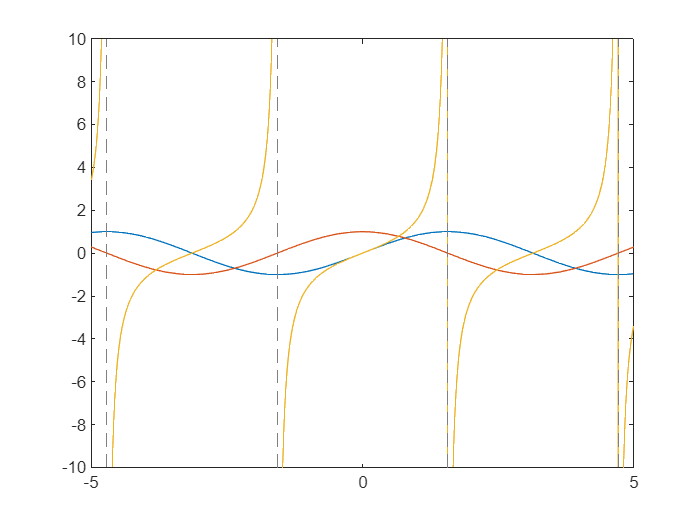

syms x
fplot([sin(x),cos(x),tan(x)])

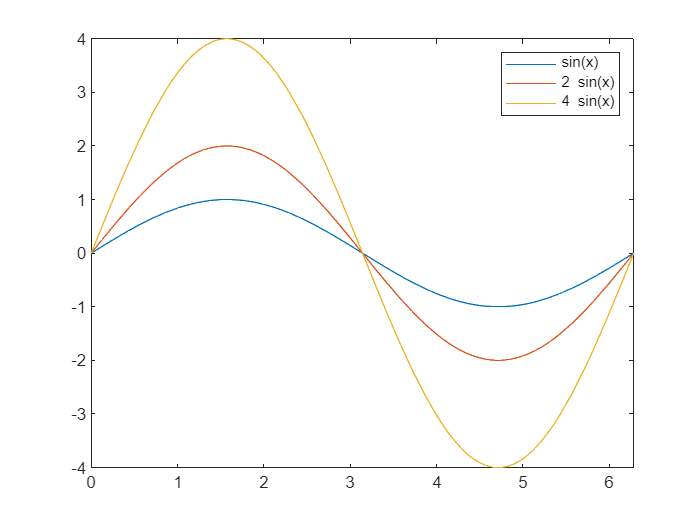

% parametric plots f(x,a) with parameter a
syms x a
expr = a*sin(x);
fplot(subs(expr,a,[1,2,4]),[0 2*pi])
legend show

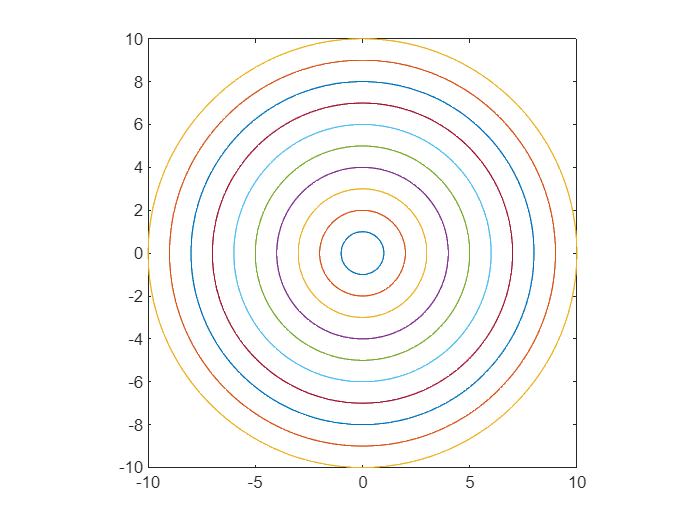

% Plotting implicit functions of type f(x,y) = r
syms x y
r = 1:10;
fimplicit(x^2 + y^2 == r.^2,[-10 10])
axis square;

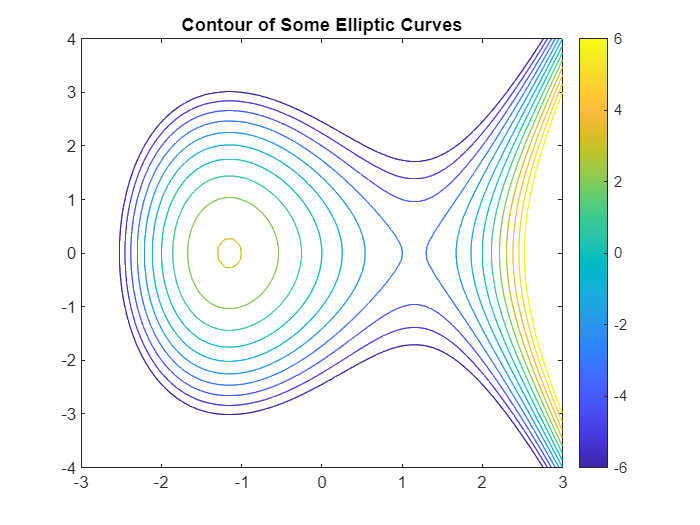

% Plot Contours of a Function f(x,y) Using fcontour
syms x y f(x,y)
f(x,y) = x^3 - 4*x - y^2;
fcontour(f,[-3 3 -4 4],'LevelList',-6:6);
colorbar
title 'Contour of Some Elliptic Curves'